folder = "C:\Users\Nickolay\Desktop\ITMO-courses\7_term\Optimal_control_theory\lab6\tex\images\";

A = [0 3; 4 0];
B = [0; 2];
Bf = [1; 1];
Q = [5 0; 0 8];

x0 = [1; 0];
T = 10;

% Поиск минимального gamma
gmin = 1;
gmax = 2;

for k = 1:40
    gamma = (gmin + gmax)/2;

    if validGamma(A, B, Bf, Q, gamma)
        gmax = gamma;
    else
        gmin = gamma;
    end
end

gamma_min = gmax;

fprintf('gamma_min = %.8f\n', gamma_min);

gamma_min = 1.36381628



% Берём значение немного выше порога
gamma = gamma_min;

[P, ~, ~] = care(A, [B Bf], Q, diag([1 -gamma^2]));

K = -B.'*P;
Acl = A + B*K;

disp('P =');

P =


disp(P);

   1.0e+04 *

    5.8772    3.4020
    3.4020    1.9694




disp('K =');

K =


disp(K);

   1.0e+04 *

   -6.8041   -3.9388




disp('eig(A+BK) =');

eig(A+BK) =


disp(eig(Acl));

   1.0e+04 *

   -0.0005
   -7.8770



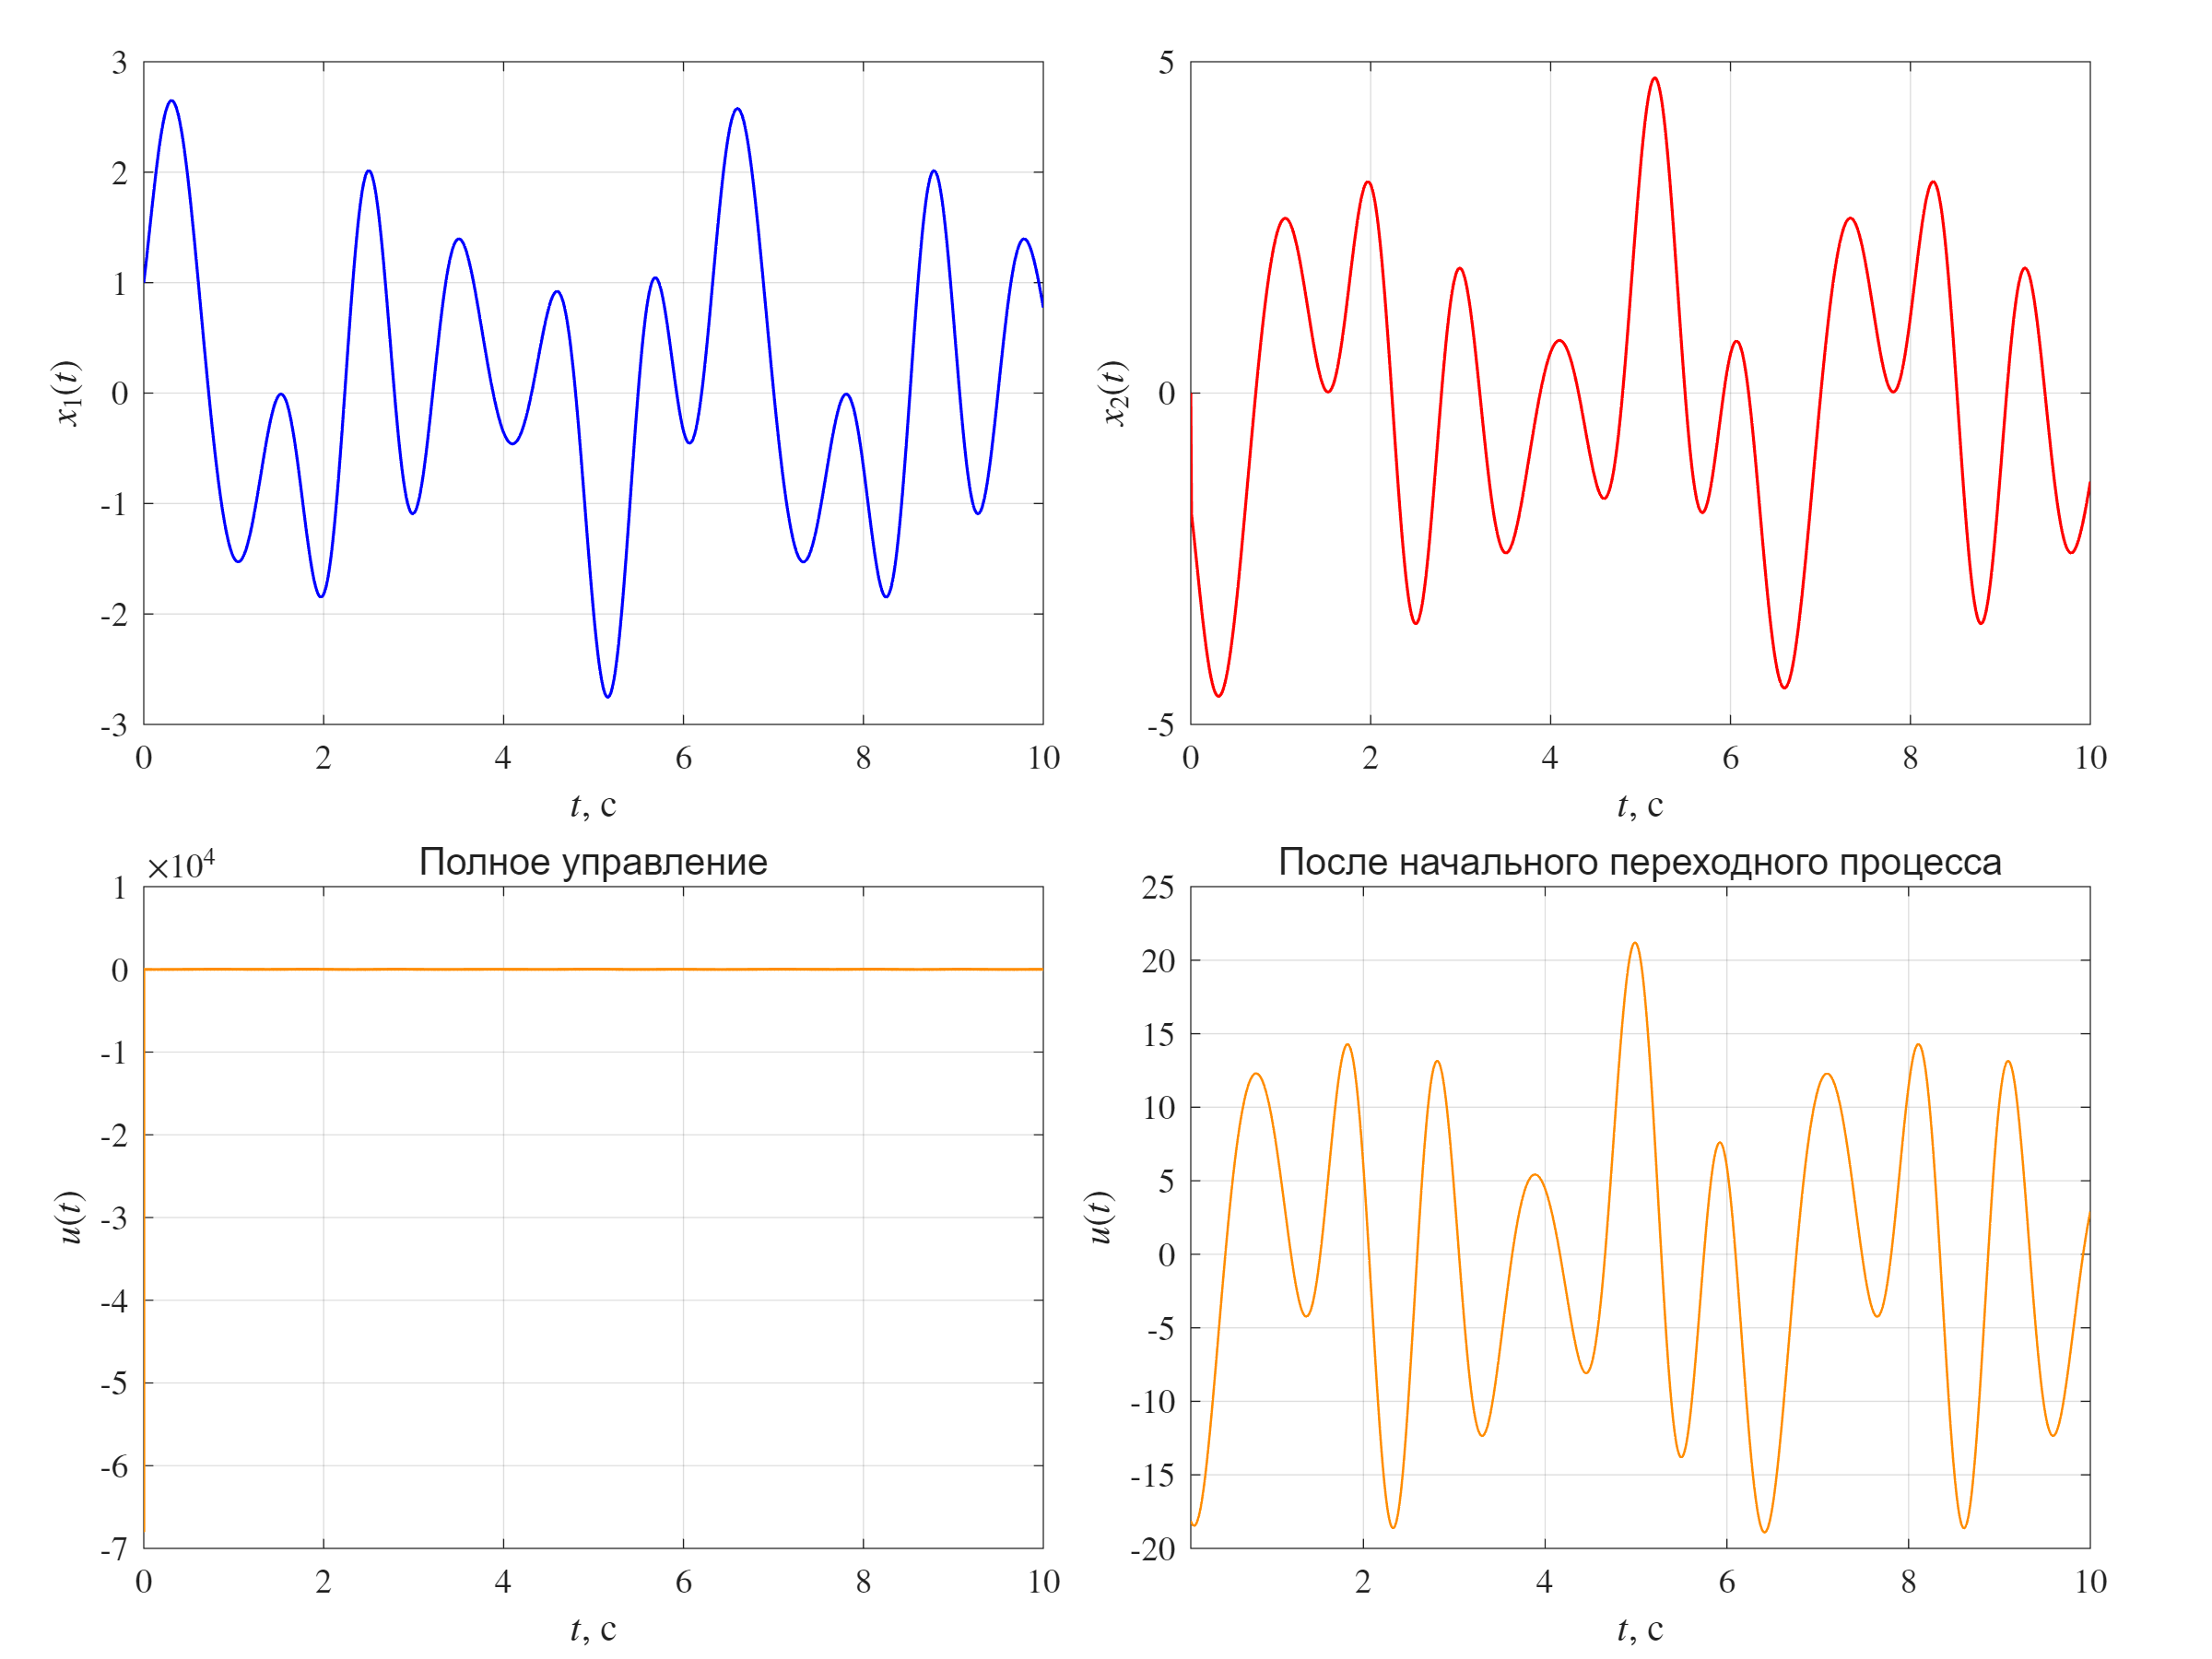


% Моделирование возмущённой системы
f = @(t) 10*sin(6*t) + 5*cos(2*t) ...
       + 4*cos(3*t) + 3*cos(8*t);

opts = odeset('RelTol', 1e-10, ...
              'AbsTol', 1e-12, ...
              'MaxStep', 0.0002);

sol = ode15s(@(t,x) Acl*x + Bf*f(t), ...
             [0 T], x0, opts);

t = (0:0.0001:T)';
x = deval(sol, t).';

u = x*K.';

% Графики

figure('Color', 'w', 'Position', [100 100 1200 900]);

tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile;
plot(t, x(:,1), 'b', 'LineWidth', 1.2);
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$x_1(t)$', 'Interpreter', 'latex');
xlim([0 T]);

nexttile;
plot(t, x(:,2), 'r', 'LineWidth', 1.2);
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$x_2(t)$', 'Interpreter', 'latex');
xlim([0 T]);

nexttile;
plot(t, u, 'Color', '#FF8C00', 'LineWidth', 1.2);
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$u(t)$', 'Interpreter', 'latex');
title('Полное управление', 'FontWeight', 'normal');
xlim([0 T]);

nexttile;
idx = t >= 0.1;
plot(t(idx), u(idx), 'Color', '#FF8C00', 'LineWidth', 0.95);
grid on;
xlabel('$t$, c', 'Interpreter', 'latex');
ylabel('$u(t)$', 'Interpreter', 'latex');
title('После начального переходного процесса', ...
    'FontWeight', 'normal');
xlim([0.1 T]);

set(findall(gcf, 'Type', 'axes'), ...
    'FontSize', 14, ...
    'TickLabelInterpreter', 'latex');

exportgraphics(gcf, fullfile(folder, 'task6_states.png'), ...
    'Resolution', 600);



% H-infinity нормы
C1 = [1 0];
C2 = [0 1];

H1 = ss(Acl, Bf, C1, 0);
H2 = ss(Acl, Bf, C2, 0);
H = ss(Acl, Bf, eye(2), zeros(2,1));

n1 = norm(H1, inf);
n2 = norm(H2, inf);
n = norm(H, inf);

fprintf('||H1||inf = %.6f\n', n1);

||H1||inf = 0.192975


fprintf('||H2||inf = %.6f\n', n2);

||H2||inf = 0.333333


fprintf('||H ||inf = %.6f\n', n);

||H ||inf = 0.385163




function ok = validGamma(A, B, Bf, Q, gamma)
    ok = false;

    try
        [P, ~, ~] = care(A, [B Bf], Q, ...
                        diag([1 -gamma^2]));

        if isempty(P) || any(~isfinite(P(:)))
            return;
        end

        P = (P + P.')/2;

        F = A - B*B.'*P + Bf*Bf.'*P/gamma^2;

        residual = A.'*P + P*A + Q ...
                 - P*B*B.'*P ...
                 + P*Bf*Bf.'*P/gamma^2;

        ok = min(eig(P)) >= -1e-7 ...
          && max(real(eig(F))) < -1e-7 ...
          && norm(residual, 'fro') < 1e-5;

    catch
        ok = false;
    end
end
